# Tunnel Characteruzation - Pitot Probe

% Take ascending pressure points starting at ~0.3 kPa and plot

pitot_cal_P = [0.4 10.18 25.04 49.90 74.50 98.63]; % Para Scientific readout (kPa)

pitot_cal_V = [0 0.543 1.365 2.742 4.105 5.444]; % Voltage readout (KSC-2 balanced at -2.6465 mV)


% Use best fit techniques to create calibration curve from collected data

PitotCal_1 = table2array(PitotCal_1);
PitotCal_2 = table2array(PitotCal_2);
PitotCal_3 = table2array(PitotCal_3);
PitotCal_4 = table2array(PitotCal_4);
PitotCal_5 = table2array(PitotCal_5);
PitotCal_6 = table2array(PitotCal_6);

Pitot_1 = table2array(Pitot_1);
Pitot_2 = table2array(Pitot_2);
Pitot_3 = table2array(Pitot_3);
Pitot_4 = table2array(Pitot_4);
Pitot_5 = table2array(Pitot_5);
Pitot_6 = table2array(Pitot_6);
Pitot_7 = table2array(Pitot_7);

% Take drvier tube calibration from Campaign 1 or 3 analysis

DCal1 = table2array(DCal1);
DCal2 = table2array(DCal2);
DCal3 = table2array(DCal3);
DCal4 = table2array(DCal4);
DCal5 = table2array(DCal5);

DT_1 = table2array(DT_Pitot1);
DT_2 = table2array(DT_Pitot2);
DT_3 = table2array(DT_Pitot3);
DT_4 = table2array(DT_Pitot4);
DT_5 = table2array(DT_Pitot5);
DT_6 = table2array(DT_Pitot6);
DT_7 = table2array(DT_Pitot7);


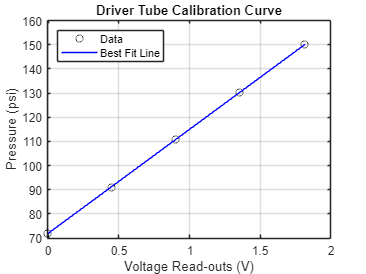

% This section plots Driver tube and Kulite calibration curves as well as
% calculates the calibration coefficients needed in later sections

% DCal data
DCal_points = [sum(DCal1)./(height(DCal1)), sum(DCal2)./(height(DCal2)), sum(DCal3)./(height(DCal3)), sum(DCal4)./(height(DCal4)), sum(DCal5)./(height(DCal5))];
DCal_pressures = [71.9 91.0 110.8 130.1 150.2];

% Calibration Curve
DCal_fit_coeffs = polyfit(DCal_pressures, DCal_points, 1);
DCal_fit = polyval(DCal_fit_coeffs, DCal_pressures);

% Plot DCal data and best-fit line
figure;
plot(DCal_points, DCal_pressures, 'ko', 'DisplayName', 'Data');
hold on
plot(DCal_fit, DCal_pressures, 'b-', 'DisplayName', 'Best Fit Line');
grid on
hold off
legend('Location', 'northwest')
ylabel('Pressure (psi)');
xlabel('Voltage Read-outs (V)');
title('Driver Tube Calibration Curve');

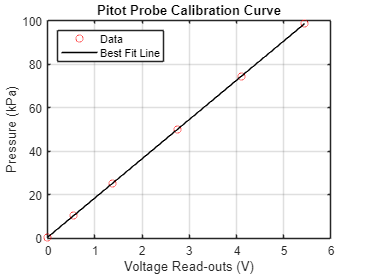

% Create mean vectors

PitotCal = [mean(PitotCal_1) mean(PitotCal_2) mean(PitotCal_3) mean(PitotCal_4) mean(PitotCal_5) mean(PitotCal_6)];

% Find best-fit line for KCal data
PitotCal_fit_coeffs = polyfit(pitot_cal_P, PitotCal, 1);
PitotCal_fit = polyval(PitotCal_fit_coeffs, pitot_cal_P);

% Plot KCal data and best-fit line
figure;
plot(pitot_cal_V, pitot_cal_P,'ro', 'DisplayName', 'Data');
hold on
plot(PitotCal_fit, pitot_cal_P, 'k-', 'DisplayName', 'Best Fit Line');
grid on
hold off
legend('Location', 'northwest')
ylabel('Pressure (kPa)');
xlabel('Voltage Read-outs (V)');
title('Pitot Probe Calibration Curve');

% Convert voltage traces to pressure traces (kPa)

Press_Pitot1 = (Pitot_1 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot2 = (Pitot_2 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot3 = (Pitot_3 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot4 = (Pitot_4 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot5 = (Pitot_5 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot6 = (Pitot_6 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot7 = (Pitot_7 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);

Press_DT1 = (DT_1 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT2 = (DT_2 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT3 = (DT_3 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT4 = (DT_4 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT5 = (DT_5 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT6 = (DT_6 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT7 = (DT_7 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);

time = linspace(-200,2000,550001); % time vector starting 200 ms before trigger


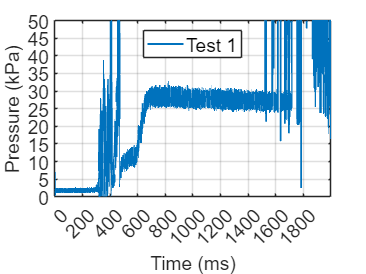

% Plot Pressure Trace

plot(time, Press_Pitot1, 'DisplayName', 'Test 1');
grid on

% Adding labels and legend

time_xlabel = 1.79; % Time in seconds displayed on x-axis of plot up to 1.79 sec

% time_xlabel + 0.2 + 0.0001

fsize = 16;
xlim([time(250000 * (0 + 0.2)) time(250000 * (2.0 + 0.2))]); ...
    % time(250000 * time elapsed(sec)), dont forget 200 ms trigger
ylim([0 50]); % kPa
set(gca,'XTick',(-200:200:2000))
set(gca,'YTick',(0:5:200))
ax=gca;
ax.XAxis.FontSize = fsize;
ax.YAxis.FontSize = fsize;
h = findobj(gca,'Type','line');
set(h,'LineWidth',1.5);
%title('Campaign #1 Pressure Traces',FontSize=fsize);
xlabel('Time (ms)',FontSize=fsize);
ylabel('Pressure (kPa)',FontSize=fsize);
legend('Location', 'north','Fontsize', fsize);
grid on

hold off;

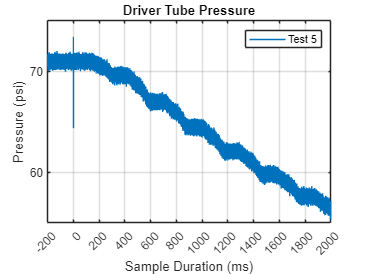

% Plot Driver Tube Pressure

% plot(time, Press_DT1, 'DisplayName', 'Test 1');
% plot(time, Press_DT2, 'DisplayName', 'Test 2');
% plot(time, Press_DT3, 'DisplayName', 'Test 3');
% plot(time, Press_DT4, 'DisplayName', 'Test 4');
plot(time, Press_DT5, 'DisplayName', 'Test 5');
% plot(time, Press_DT6, 'DisplayName', 'Test 6');
% plot(time, Press_DT7, 'DisplayName', 'Test 7');

% Adding labels and legend

time_xlabel = 1.79; % Time in seconds displayed on x-axis of plot up to 1.79 sec

% Adding labels and legend
xlim([time(1) time(end)]);
set(gca,'XTick',(-200:200:2000))
set(gca,'YTick',(20:10:160))
title('Driver Tube Pressure');
xlabel('Sample Duration (ms)');
ylabel('Pressure (psi)');
grid on
legend('show');

hold off;

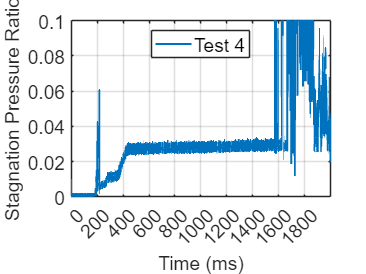

% Create stagnation pressure ratio arrays

Po2_Po1_Run1 = Press_Pitot1 ./ (6.89476 * Press_DT1);
Po2_Po1_Run2 = Press_Pitot2 ./ (6.89476 * Press_DT2);
Po2_Po1_Run3 = Press_Pitot3 ./ (6.89476 * Press_DT3);
Po2_Po1_Run4 = Press_Pitot4 ./ (6.89476 * Press_DT4);
Po2_Po1_Run5 = Press_Pitot5 ./ (6.89476 * Press_DT5);
Po2_Po1_Run6 = Press_Pitot6 ./ (6.89476 * Press_DT6);
Po2_Po1_Run7 = Press_Pitot7 ./ (6.89476 * Press_DT7);

% Plot stagantion pressure ratio traces

 % plot(time, Po2_Po1_Run1, 'DisplayName', 'Test 1');
 % plot(time, Po2_Po1_Run2, 'DisplayName', 'Test 2');
 % plot(time, Po2_Po1_Run3, 'DisplayName', 'Test 3');
 plot(time, Po2_Po1_Run4, 'DisplayName', 'Test 4');
 % plot(time, Po2_Po1_Run5, 'DisplayName', 'Test 5');
 % plot(time, Po2_Po1_Run6, 'DisplayName', 'Test 6');
 % plot(time, Po2_Po1_Run7, 'DisplayName', 'Test 7');

 % Adding labels and legend

time_xlabel = 1.79; % Time in seconds displayed on x-axis of plot up to 1.79 sec

% time_xlabel + 0.2 + 0.0001

fsize = 16;
xlim([time(250000 * (0 + 0.2)) time(250000 * (2.0 + 0.2))]); ...
    % time(250000 * time elapsed(sec)), dont forget 200 ms trigger
ylim([0 0.1]); % kPa
set(gca,'XTick',(-200:200:2000))
set(gca,'YTick',(0:0.02:0.1))
ax=gca;
ax.XAxis.FontSize = fsize;
ax.YAxis.FontSize = fsize;
h = findobj(gca,'Type','line');
set(h,'LineWidth',1.5);
%title('Campaign #1 Pressure Traces',FontSize=fsize);
xlabel('Time (ms)',FontSize=fsize);
ylabel('Stagnation Pressure Ratio',FontSize=fsize);
legend('Location', 'north','Fontsize', fsize);
grid on

hold off;

% Determine Tunnel noise via pressure trace deviation from mean

Tstart = 0.75; % time elapsed where steady state begins (sec)
Tend = 1.5; % time elapsed where steady state ends (sec)


Pressmean = mean(Press_Pitot1([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])) % (kPa)

Pressmean = 27.5933


deviation = std(Press_Pitot1([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])) % (kPa)

deviation = 0.8700


Meanremoved = Press_Pitot1 - Pressmean;

rootms_withmean = rms(Press_Pitot1([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))]), 1) % (kPa)

rootms_withmean = 27.6071


rootms_removed = rms(Meanremoved([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))]), 1) % (kPa)

rootms_removed = 0.8700


noise = 100 * (rootms_removed / Pressmean) % Percent noise level

noise = 3.1530


% THISE DOESNT WORK!!! This doesn't take into account the cavity reseonance
% frequency of the kulite, Use a PSD to only analyze physical tunnel noise
% and examine portions of the run against the driver tube pressure "humps"


## PSD Calc

figure

hold on
fsamp = 250*10^3

fsamp = 250000

pointsperblock = 1000;
smoothened = 0;

Tstart = 0.35; % time elapsed where steady state begins (sec)
Tend = 0.375; % time elapsed where steady state ends (sec)


Pressmean = mean(Press_Pitot5([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])) % (kPa)

Pressmean = 12.6421

noMean = Press_Pitot5([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])-Pressmean;

[Sxx_mean,LLL] = PSD(noMean,fsamp,pointsperblock,smoothened)

Sxx_mean = 1.0e-04 *

    0.0467
    0.0631
    0.1035
    0.1244
    0.1192
    0.0907
    0.0837
    0.0539
    0.0438
    0.0481


LLL =            0         250         500         750        1000        1250        1500        1750        2000        2250        2500        2750        3000        3250        3500        3750        4000        4250        4500        4750        5000        5250        5500        5750        6000        6250        6500        6750        7000        7250        7500        7750        8000        8250        8500        8750        9000        9250        9500        9750       10000       10250       10500       10750       11000       11250       11500       11750       12000       12250


StanDev = sqrt(trapz(LLL(1:200),Sxx_mean(1:200)))

StanDev = 0.2705


(StanDev/Pressmean)*100

ans = 2.1395

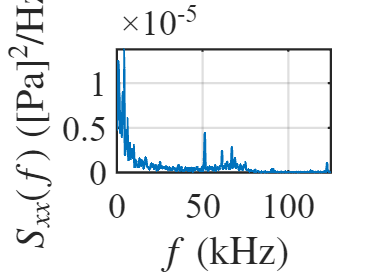


hold off

% Noise levels
               
                  % DT (psi)    Vac (kPa)   

% noise1 = 1.56%       151.2       1.7              
% noise2 = 1.54%       149.5       1.7
% noise3 = 1.61%       120.4       1.16
% noise4 = 1.81%       91.0        0.55
% noise5 = 2.14%       70.9        0.67
% noise6 = 2.29%       50.8        0.53
% noise7 = 2.6%        30.3        0.37


% Average Mach number calculation

% Mach number during steady-state run time 

% Find Mean of steady-state run time stagnation pressure, Po2 just passed Normal Shock

Po2 = mean(Press_Pitot2([(250000 * (Tstart + 0.2)) (250000 * (Tend + 0.2))])) % (kPa)

% Find Mean of corresponding Driver Tube pressure, Po1, convert to kPa

Po1 = 6.89476 * mean(Press_DT2([(250000 * (Tstart + 0.2)) (250000 * (Tend + 0.2))])) % (kPa)

% Find Po2 / Po1

Avg_Po2_Po1 = Po2 / Po1

% Solve for Upstream Mach Number using Po2/Po1 via Normal Shock Relations
% Note: simplified for gamma = 1.4

NormalShockRelation = @(M) ((2.4 * M^2) / (0.4 * M^2 + 2))^3.5 * ...
    (2.4 / (2.8 * M^2 - 0.4))^2.5 - Avg_Po2_Po1;

Avg_Minf = fzero(NormalShockRelation, [1,7]) % [1,7] being the range of guesses
